# Statistical Learning

We assume that we are interested in learning about/modelling some system/process in the world.  We don't have full access to the system or complete knowledge about how it works, but we can sample data/measurements relating to it.

Because of our lack of knowledge, we model this as a random process (e.g. coin toss).

x = round(rand(20,1))

x =      0
     0
     1
     1
     1
     0
     1
     1
     0
     1


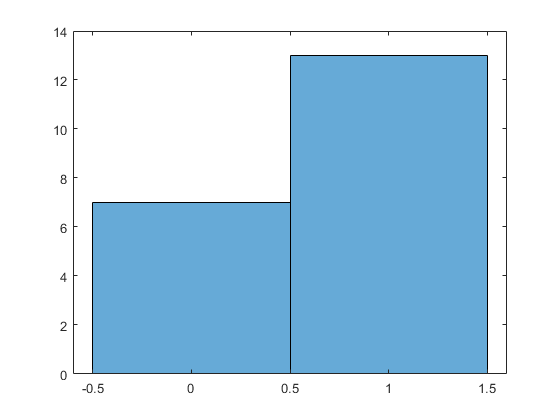

figure
histogram(x)

pheads = sum(x)/20 %Why is this sensible?

pheads = 0.6500

ptails = 1 - pheads

ptails = 0.3500

Our model is a **probability distribution**.  Learning is estimating its parameters.

## Classification (two-class)

Output: $C \in \{0,1\}$

Input: $\mathbf{x}$

Choose $C = 1$ if $P(C=1|\mathbf{x}) > 0.5$, else choose $C=0$.

Alternatively, we can think about a **discriminant function** that makes this decision.

Choose $C=1$ if $g_1(\mathbf x) > g_0(\mathbf x)$, else choose $C=0$

We will see later that there is an implicit **threshold** value here (0.5, or "equal") that can be varied.

## [Bayes](https://en.wikipedia.org/wiki/Thomas_Bayes) Rule

Remember that we will have some training data ((input, output) examples) to build our classifier.  Bayes Rule tells us what to do!


$$P(C|\mathbf x) = \frac{P(\mathbf x | C)P(C)}{p(\mathbf x)}$$



$$\mathrm{Posterior} = \frac {\mathrm{Likelihood} \times \mathrm{Prior}} {\mathrm{Evidence}}$$


We also from probability that:


$$P(C=0) + P(C=1) = 1$$


$P(C=0|\mathbf x) + P(C=1|\mathbf x) = 1$(posterior probabilities sum to 1)


$$p(x) = p(x | C=0)P(C=0) + p(x | C=1)P(C=1)$$


We often write Bayes Rule as:


$$P(C|x) = \frac{P(x | C)P(C)}{p(x | C=0)P(C=0) + p(x | C=1)P(C=1)}$$


The left-hand side is what we want, so we can get it by building the right-hand side.

## Maximum Likelihood Estimation (MLE)

**Likelihood Function:**

$l(\theta | \mathcal{X}) = p(\mathcal{X} | \theta) = \prod_t p({x}_t | \theta)$, where $t$ is the training set index.

Log-likelihood Function:


$$L(\theta|\mathcal{X}) = \log l(\theta|\mathcal{X}) = \sum_t \log p(x_t | \theta)$$


MLE suggests we find $\theta^* = \arg \max_{\theta} L(\theta|\mathcal{X})$

This is an optimisation problem over the model parameter vector, $\theta$.

[Examples from Alpaydin: Bernoulli, multinomial, Gaussian.]

## Prediction via Bayes Rule

Given a dataset, $\mathcal{X}$, we:

- build class-conditional densities $p(x | C_0)$ and $p(x|C_1)$

- estimate/make up the class priors $P(C_0)$ and $P(C_1)$

- predict $P(C_0|x)$, $P(C_1|x) = 1 = P(C_0|x)$

priorh = 0.7;
priort = 0.3;
headpost = (pheads*priorh)/((pheads*priorh)+(ptails*priort))

headpost = 0.8125

tailpost = 1-headpost

tailpost = 0.1875

1-D Gaussian examples from Alpaydin (and this week's prac)

## Regression

MLE seems like a sensible way to learning a model.  How does it apply to regression?

[We will look at the Alpaydin book.]

- Linear regression

- Polynomial regression

## Bias and Variance

The error equation for a model can be rewritten in a way that helps us understand the effects of model complexity, overfitting and underfitting and sample size.

## Model Selection

Key concepts here that we will make use of through the course:

- **Cross-validation**: a technique for estimating generalisation accuracy using "held-out" data.  Can than be used to do model selection and hyperparameter fitting.

- **Regularisation**: techniques for controlling/penalizing model complexity.

[For a bit of philosophy: [Occam's razor](https://en.wikipedia.org/wiki/Occam's_razor)!]

## Multivariate Statistical Learning

If $\mathbf x}$ is $d$-dimensional, we need to build and work with multivariate probability distributions.

e.g. the multivariate Normal or Gaussian distribution, $\mathcal{N}(\mu,\Sigma)$, where $\mu$ is the mean vector and $\Sigma$ is the covariance matrix.

The way that $\Sigma$ is parameterized determines the "power" or "flexibility" of the resulting classifier.

**Simplest case:** all classes & variables have equal variances; no covariances.

load hogg
hogg

hogg =     24    14    11     7    19
    15     7     9     7    24
    21    12     7     4    19
    27    17    13     7    15
    33    14    12    12    10
    23    16    18    18    20


diag(var(hogg))

ans =    36.1667         0         0         0         0
         0   12.6667         0         0         0
         0         0   14.2667         0         0
         0         0         0   25.3667         0
         0         0         0         0   22.9667


Note that:

- The discriminant is linear

- We will predict the class according to the closest mean (aka template matching)

**Most General case:** full, different covariance matrices for each class.

cov(hogg)

ans =    36.1667   15.0667    7.7333    9.0333  -28.0333
   15.0667   12.6667    8.9333    7.3333   -9.9333
    7.7333    8.9333   14.2667   17.0667   -3.0667
    9.0333    7.3333   17.0667   25.3667   -3.7667
  -28.0333   -9.9333   -3.0667   -3.7667   22.9667


Note that:

- The discriminant is quadratic

- We will predict the class according to the "nearest pdf", using Mahalanobis distance: $(\mathbf{x - \mu})^T \Sigma^{-1} (\mathbf{x - \mu})$

See book for in-between cases.

Classification is as before, using Bayes rule.

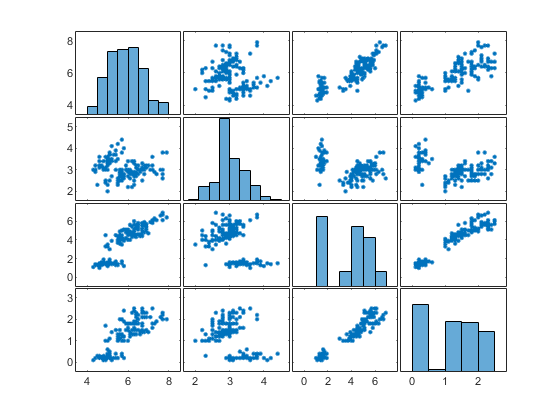

%Multivariate parametric classification demo

load fisheriris
plotmatrix(meas)

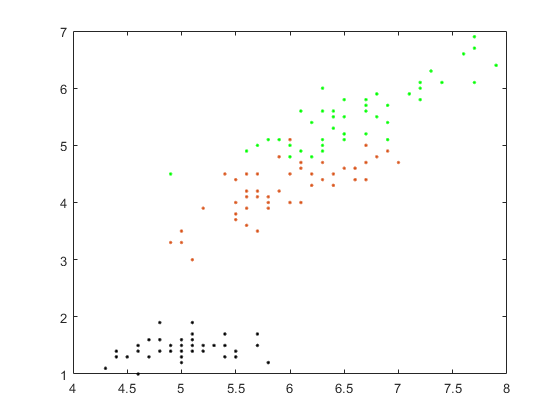

%species
data = [meas(:,1) meas(:,3)];
figure
plot(data(1:50,1),data(1:50,2),'k.')
hold on
plot(data(51:100,1),data(51:100,2),'.')
plot(data(101:150,1),data(101:150,2),'g.')

m1 = mean(data(101:150,:))

m1 =     6.5880    5.5520


c1 = cov(data(101:150,:))

c1 =     0.4043    0.3033
    0.3033    0.3046


c1 = eye*diag(c1)'

c1 =     0.4043    0.3046


%help mvnpdf
[X1,X2] = meshgrid(linspace(0,8,50)', linspace(0,8,50)');
X = [X1(:) X2(:)];
p = mvnpdf(X,m1,c1);
figure
surf(X1,X2,reshape(p,50,50));
m2 = mean(data(51:100,:))

m2 =     5.9360    4.2600


c2 = cov(data(51:100,:))

c2 =     0.2664    0.1829
    0.1829    0.2208


c2 = eye*diag(c2)'

c2 =     0.2664    0.2208


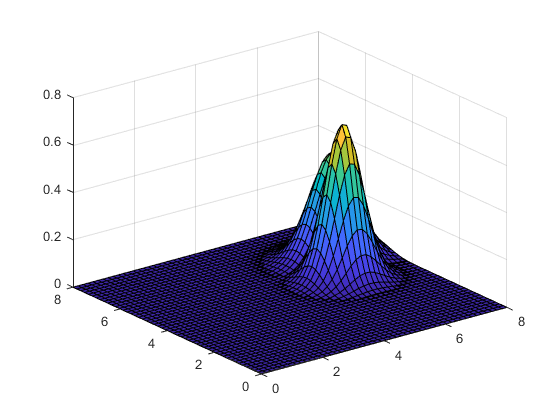

hold on
p2 = mvnpdf(X,m2,c2);
surf(X1,X2,reshape(p2,50,50));


testx = [2.5 5]

testx =     2.5000    5.0000


a = mvnpdf(testx,m1,c1);
b = mvnpdf(testx,m2,c2)

b = 4.5325e-11

a

a = 2.9143e-10

a/(a+b)

ans = 0.8654

b/(a+b)

ans = 0.1346

**Discrete Features**

e.g. bag of words representation

**Multivariate Regression**

Math looks nasty but the extension to $d$-D is easy.